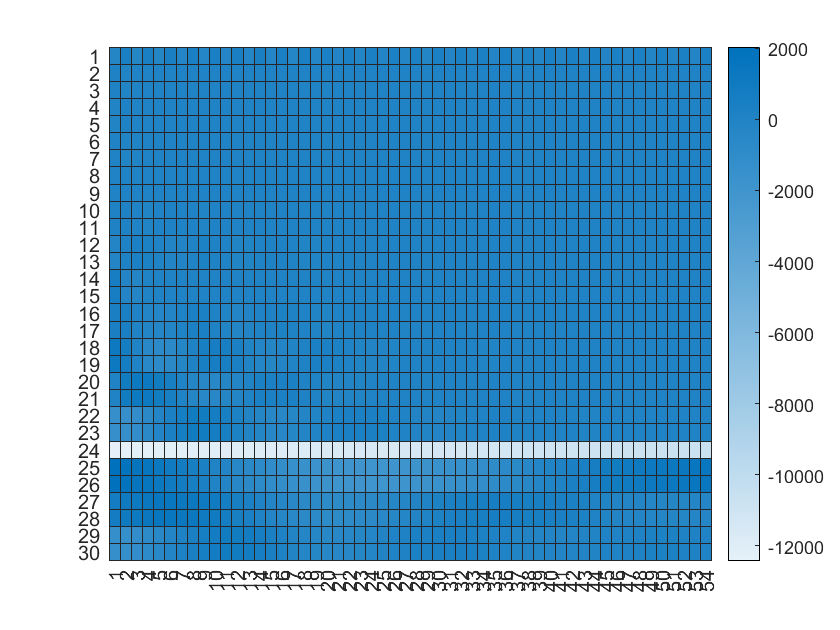

figure
heatmap(real(dmd.timeDynamics))


timeDynamics = real(dmd.timeDynamics)

timeDynamics = 	1.0e+04 *

   -0.0359    0.0355   -0.0350    0.0345   -0.0341    0.0336   -0.0332    0.0327   -0.0323    0.0319   -0.0315    0.0310   -0.0306    0.0302   -0.0298    0.0294   -0.0290    0.0287   -0.0283    0.0279   -0.0275    0.0272   -0.0268    0.0265   -0.0261    0.0258   -0.0254    0.0251   -0.0248    0.0244   -0.0241    0.0238   -0.0235    0.0232   -0.0229    0.0226   -0.0223    0.0220   -0.0217    0.0214   -0.0211    0.0208   -0.0205    0.0203   -0.0200    0.0197   -0.0195    0.0192   -0.0190    0.0187
    0.0083   -0.0061    0.0042   -0.0026    0.0015   -0.0006    0.0001    0.0003   -0.0004    0.0005   -0.0005    0.0004   -0.0003    0.0003   -0.0002    0.0001   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000  

figure
heatmap(timeDynamics)


figure
rtimeDynamics = rescale(timeDynamics);
%image(rtimeDynamics)

timeDynamics(24,:) = []

timeDynamics = 	1.0e+03 *

   -0.3594    0.3546   -0.3499    0.3453   -0.3407    0.3362   -0.3318    0.3274   -0.3231    0.3188   -0.3146    0.3104   -0.3063    0.3023   -0.2983    0.2943   -0.2904    0.2866   -0.2828    0.2790   -0.2754    0.2717   -0.2681    0.2646   -0.2611    0.2576   -0.2542    0.2509   -0.2475    0.2443   -0.2410    0.2379   -0.2347    0.2316   -0.2285    0.2255   -0.2225    0.2196   -0.2167    0.2138   -0.2110    0.2082   -0.2055    0.2027   -0.2001    0.1974   -0.1948    0.1922   -0.1897    0.1872
    0.0827   -0.0608    0.0417   -0.0263    0.0146   -0.0062    0.0006    0.0027   -0.0044    0.0050   -0.0048    0.0042   -0.0035    0.0027   -0.0019    0.0013   -0.0008    0.0004   -0.0002   -0.0000    0.0001   -0.0002    0.0002   -0.0002    0.0001   -0.0001    0.0001   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000  

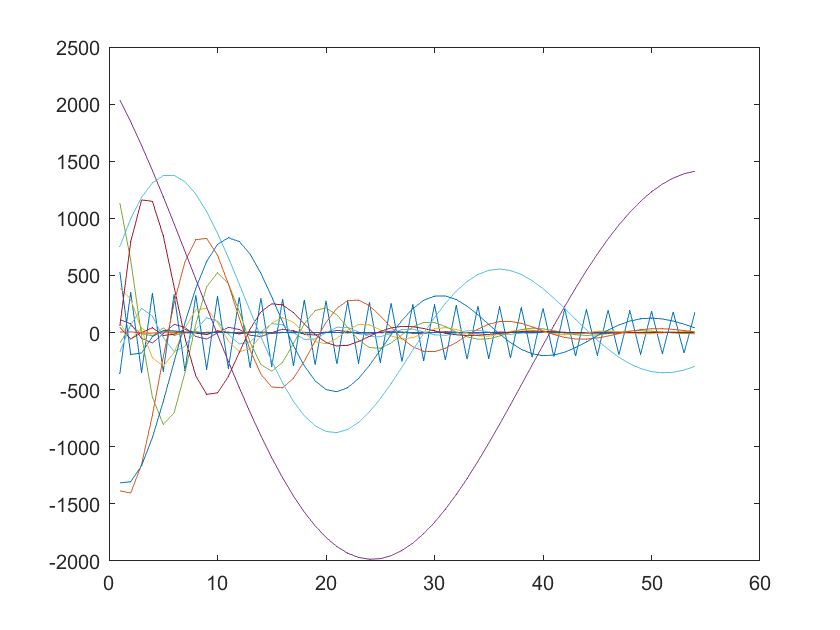


figure
plot(timeDynamics')

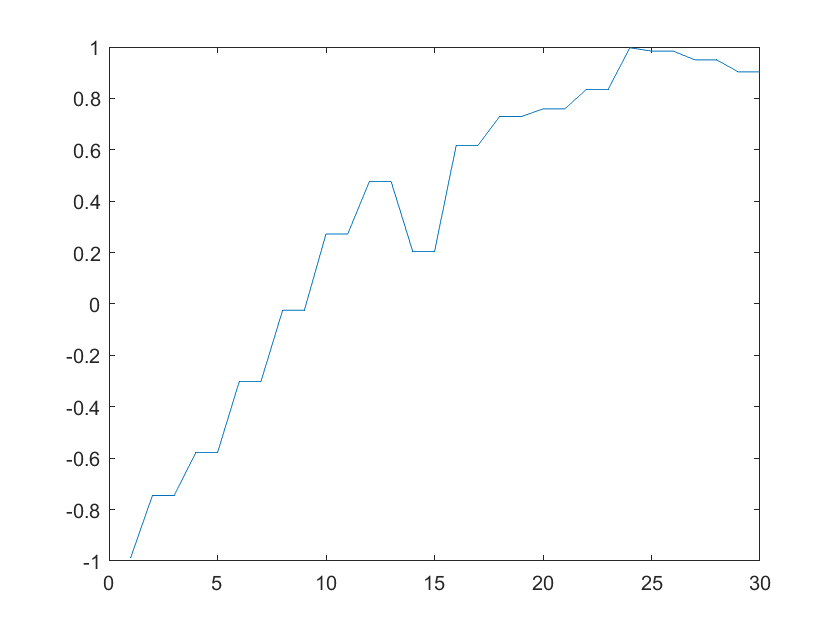

figure(gcf)


figure

%{
% drawline()
for i = 1:size(timeDynamics,1)
    fprintf('mode %i',i);
    figure
    plot(timeDynamics(i,:))
end
%}

plot(real(dmd.descreteTimeEigenValues))

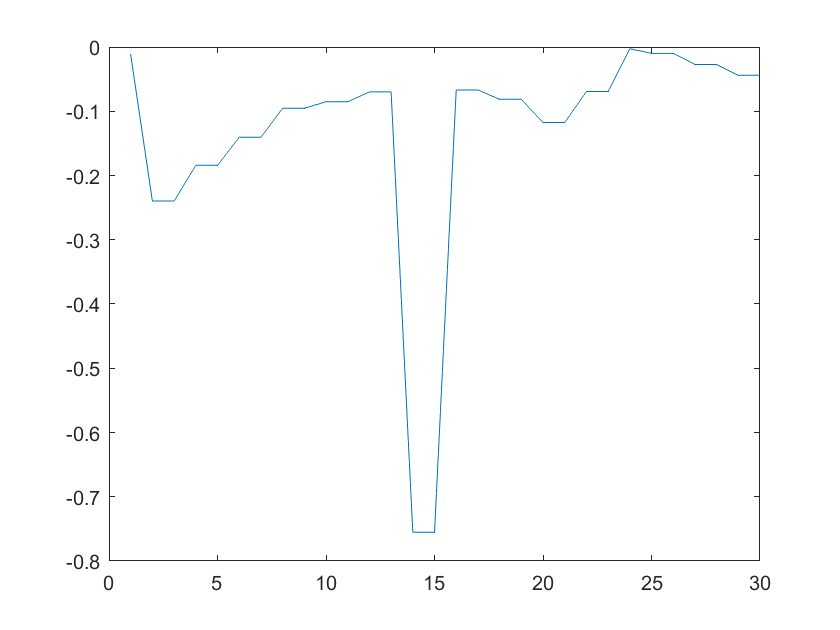


plot(real(dmd.continuousTimeEigenValues))

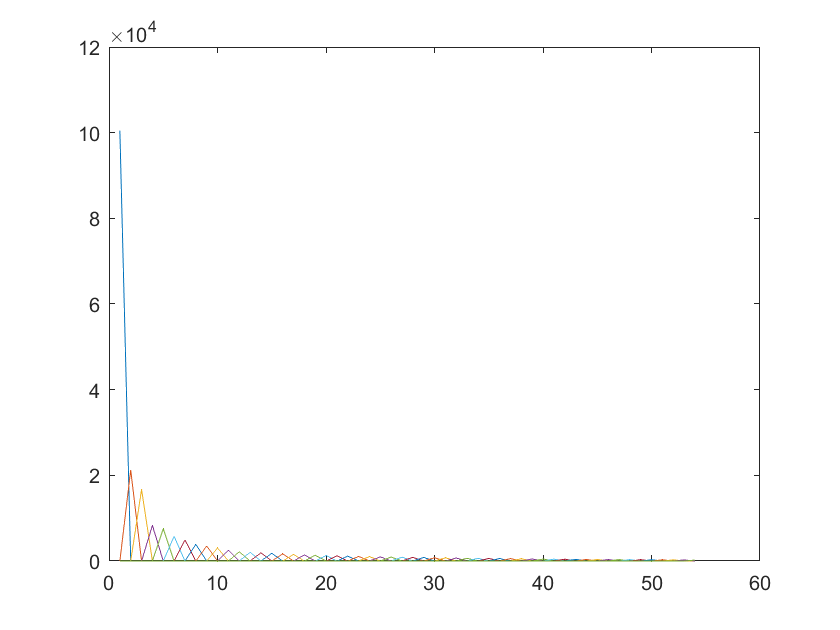




x = dmd.snapshotMatrix(:,1:end-1);
[U, SIGMA, V] = svd(x,'econ');
plot(SIGMA);

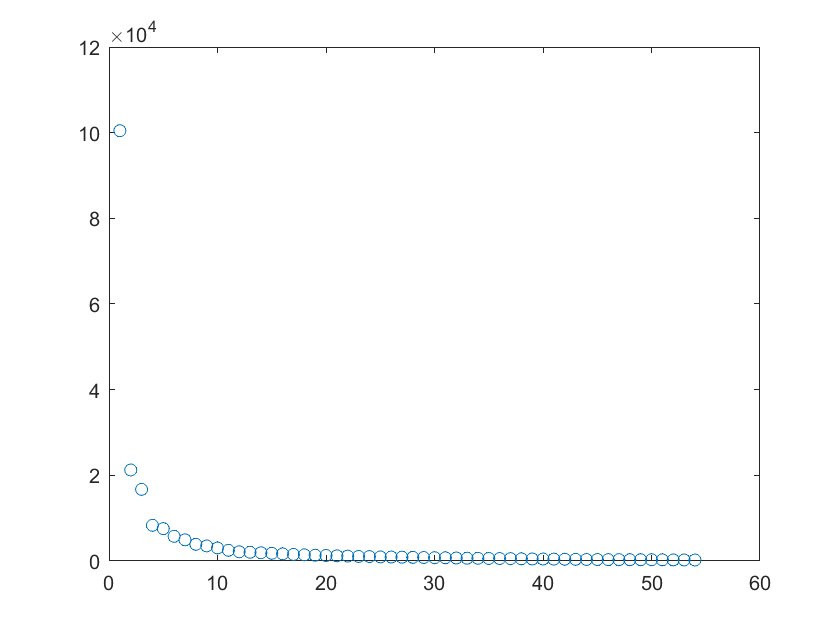

plot(diag(SIGMA),'o');